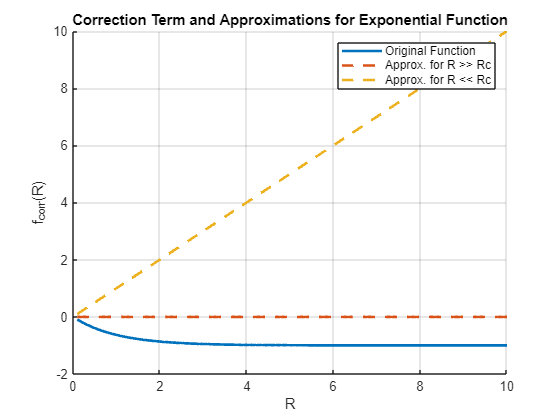

% Parameters
beta = 1;             % Example value for beta
Rc = 1;               % Example value for Rc (characteristic radius)
R = linspace(0.1, 10, 500); % Range of R values (avoid R = 0)

% Original function
f_corr_new = -beta * Rc .* (1 - exp(-R / Rc));

% High curvature approximation (R >> Rc)
f_corr_approx_high_new = zeros(size(R)); % Function vanishes for high curvature

% Low curvature approximation (R << Rc)
f_corr_approx_low_new = beta * R; % Linear approximation for low curvature

% Plotting the functions
figure;
hold on;

% Plot original function
plot(R, f_corr_new, 'LineWidth', 2, 'DisplayName', 'Original Function');

% Plot approximations
plot(R, f_corr_approx_high_new, '--', 'LineWidth', 2, 'DisplayName', 'Approx. for R >> Rc');
plot(R, f_corr_approx_low_new, '--', 'LineWidth', 2, 'DisplayName', 'Approx. for R << Rc');

% Add labels and title
xlabel('R');
ylabel('f_{corr}(R)');
title('Correction Term and Approximations for Exponential Function');
legend;
grid on;
hold off;